%% Option B: Compare Segmentation Routes on rice.png
clear; clc; close all;
fprintf('MATLAB Version: %s\n', version);

MATLAB Version: 26.2.0.3437455 (R2026b) Update 2



% Create results directory for repository submission
if ~exist('results', 'dir')
    mkdir('results');
end

% Load reference image without added noise
R = imread('rice.png');

%% 1. Three Segmentation Routes + Identical Cleaning
% Route 1: Global Otsu threshold on the raw image
BW1_raw = imbinarize(R);
BW1 = bwareaopen(BW1_raw, 50);

% Route 2: Morphological background correction + Otsu
bg = imopen(R, strel('disk', 15));
R_corr = imadjust(imsubtract(R, bg));
BW2_raw = imbinarize(R_corr);
BW2 = bwareaopen(BW2_raw, 50);

% Route 3: Local adaptive thresholding (sensitivity = 0.5) on raw image
BW3_raw = imbinarize(R, adaptthresh(R, 0.5));
BW3 = bwareaopen(BW3_raw, 50);

%% 2. Label Connected Components and Compute Area Statistics
[L1, n1] = bwlabel(BW1);
[L2, n2] = bwlabel(BW2);
[L3, n3] = bwlabel(BW3);

s1 = regionprops(L1, 'Area'); areas1 = [s1.Area];
s2 = regionprops(L2, 'Area'); areas2 = [s2.Area];
s3 = regionprops(L3, 'Area'); areas3 = [s3.Area];

Route = {'Route 1: Global Otsu (Raw)'; ...
    'Route 2: Background Correction + Otsu'; ...
    'Route 3: Adaptive Threshold (Sensitivity 0.5)'};
Grain_Count  = [n1; n2; n3];
Mean_Area_px = round([mean(areas1); mean(areas2); mean(areas3)], 2);
Std_Area_px  = round([std(areas1);  std(areas2);  std(areas3)], 2);

summary_table = table(Route, Grain_Count, Mean_Area_px, Std_Area_px);
disp(summary_table);

                          Route                          Grain_Count    Mean_Area_px    Std_Area_px
    _________________________________________________    ___________    ____________    ___________

    {'Route 1: Global Otsu (Raw)'                   }        87            191.93          76.16   
    {'Route 2: Background Correction + Otsu'        }        93             189.1          53.92   
    {'Route 3: Adaptive Threshold (Sensitivity 0.5)'}        93            191.85          54.74   



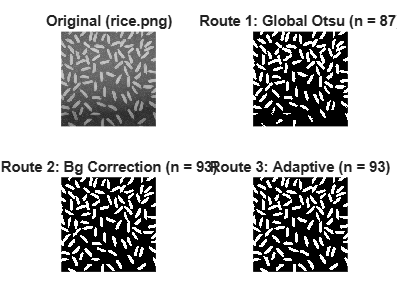


% Save summary metrics table to results/
writetable(summary_table, fullfile('results', 'segmentation_metrics.csv'));

%% 3. Visualizations: Masks, Labelled Image, and Dark-Corner Inspection

% Figure 1: Original image and the three cleaned binary masks (2x2 layout)
fig1 = figure('Name', 'Segmentation Masks Comparison');
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(R);   title('Original (rice.png)');
nexttile; imshow(BW1); title(sprintf('Route 1: Global Otsu (n = %d)', n1));
nexttile; imshow(BW2); title(sprintf('Route 2: Bg Correction (n = %d)', n2));
nexttile; imshow(BW3); title(sprintf('Route 3: Adaptive (n = %d)', n3));

exportgraphics(fig1, fullfile('results', 'fig1_three_masks.png'), 'Resolution', 200);

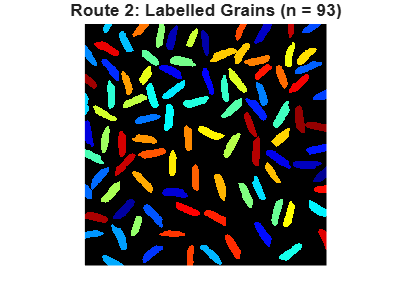


% Figure 2: Labelled image for the most reliable route (Route 2)
fig2 = figure('Name', 'Labelled Grains (Route 2)');
imshow(label2rgb(L2, 'jet', 'k', 'shuffle'));
title(sprintf('Route 2: Labelled Grains (n = %d)', n2));

exportgraphics(fig2, fullfile('results', 'fig2_labelled_route2.png'), 'Resolution', 200);

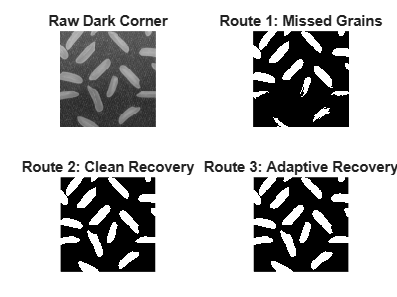


% Figure 3: Visual inspection of the dark bottom-left corner (2x2 layout)
rows = 157:256; cols = 1:100;
fig3 = figure('Name', 'Dark Corner Zoom Inspection');
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(R(rows, cols));   title('Raw Dark Corner');
nexttile; imshow(BW1(rows, cols)); title('Route 1: Missed Grains');
nexttile; imshow(BW2(rows, cols)); title('Route 2: Clean Recovery');
nexttile; imshow(BW3(rows, cols)); title('Route 3: Adaptive Recovery');

exportgraphics(fig3, fullfile('results', 'fig3_dark_corner_zoom.png'), 'Resolution', 200);

Visual Region Inspection & Trusted Route (Dark Bottom-Left Corner)

Inspecting the dark bottom-left corner of rice.png (rows 157:256, cols 1:100) by eye clearly shows why uneven illumination breaks global thresholding. In Route 1 (Global Otsu), several dim rice grains in the shadowed corner fall below the single global threshold and disappear completely. In Route 3 (Adaptive Thresholding, sensitivity 0.5), those dark-corner grains are detected, but the local threshold also picks up background noise in low-contrast areas, producing rougher edges and minor false foreground fragments. I trust Route 2 (Background Correction + Otsu) best for this image: estimating the background illumination with imopen(R, strel('disk', 15)) and subtracting it flattens the shadow gradient so global Otsu recovers the dark-corner grains cleanly with smooth, well-defined boundaries.

Limitation of the Analysis

A key limitation of this analysis is the presence of touching rice grains combined with the lack of a ground-truth segmentation mask. Because all three routes use the same morphological cleaning step (bwareaopen(BW, 50)) without watershed splitting or boundary separation, touching grains remain merged into a single connected component during bwlabel, which undercounts the true number of grains and inflates both the mean area and standard deviation. In addition, because rice.png has no pixel-accurate ground truth, segmentation accuracy can only be judged visually and through component statistics rather than exact pixel-level metrics such as Intersection over Union (IoU) or precision and recall.